# SysMIC M1: Assignment 4

If you need help for this assignment please make use of the [session 4 forum](http://sysmic.ac.uk/moodle/mod/forum/view.php?id=2549). 

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2386](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2386). 

After submission you can access model answers via the [session 4 review](http://sysmic.ac.uk/moodle/mod/quiz/view.php?id=3200) activity.

`NAME: Jade Lau`

## Exercise 1.1.13

1. Look at this network.

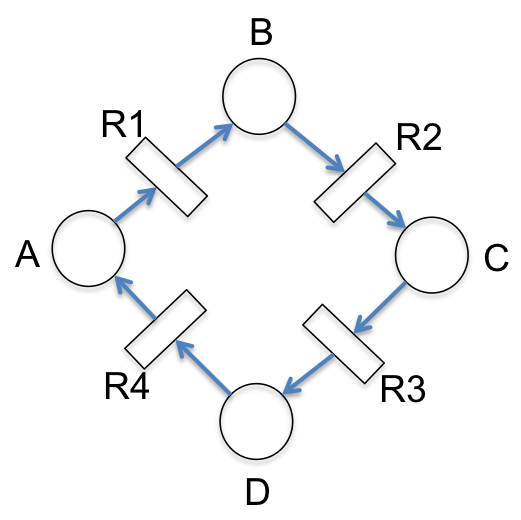

a) Without doing any calculations can you identify any

i) conservation laws

*Answer: 1 where all reactions fire*

ii) sets of reactions which will leave the state unchanged?

*Answer: R1: A -> B , R2: B -> C, R3: C->D, R4: D->A*

b) We will define the species and reaction vectors to be $\mathit{\mathbf{s}}={\left\lbrack \mathit{\mathbf{A}}\;\mathit{\mathbf{B}}\;\mathit{\mathbf{C}}\;\mathit{\mathbf{D}}\right\rbrack }^{\mathit{\mathbf{T}}\;}$and $\mathit{\mathbf{r}}={\left\lbrack \textrm{R1}\;\textrm{R2}\;\textrm{R3}\;\textrm{R4}\right\rbrack }^{\mathit{\mathbf{T}}\;}$

In MATLAB construct the corresponding Petri net matrices ${\mathit{\mathbf{W}}}_{\textrm{sr}}$, ${\mathit{\mathbf{W}}}_{\textrm{rs}}$. 

%answer
W_sr = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

W_sr =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


W_rs = [0 1 0 0; 0 0 1 0; 0 0 0 1; 1 0 0 0]

W_rs =      0     1     0     0
     0     0     1     0
     0     0     0     1
     1     0     0     0


c) Use these to calculate reaction matrix **A** and stoichiometry matrix **S**.

%answer
% Reaction matrix (output - input)
A = W_sr - W_rs;

% Stoichiometry matrix
S = A';


d) Calculate the P and T invariants for this system and comment on their meanings. Did you identify them in part (a)?

%answer
P = null(A, 'r')

P =      1
     1
     1
     1


T = null(S, 'r')

T =      1
     1
     1
     1



%yes.



Comments:

2. Look at this network.

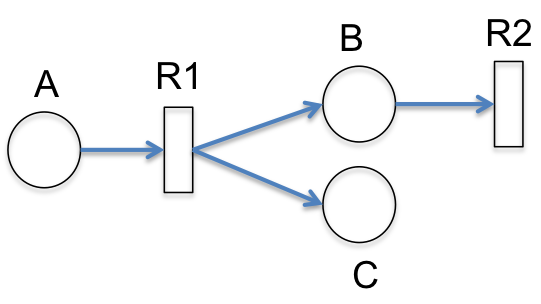

a) Without doing any calculations can you identify any

i) conservation laws

*Answer: 1 *

ii) sets of reactions which will leave the state unchanged?

*Answer: R1: A -> B +C and R2: B -> *∅

b) We will define the species and reaction vectors to be $\mathit{\mathbf{s}}={\left\lbrack \mathit{\mathbf{A}}\;\mathit{\mathbf{B}}\;\mathit{\mathbf{C}}\right\rbrack }^{\mathit{\mathbf{T}}\;}$and $\mathit{\mathbf{r}}={\left\lbrack \textrm{R1}\;\textrm{R2}\;\right\rbrack }^{\mathit{\mathbf{T}}\;}$

In MATLAB construct the corresponding Petri net matrices ${\mathit{\mathbf{W}}}_{\textrm{sr}}$, ${\mathit{\mathbf{W}}}_{\textrm{rs}}$. 

%answer
W_sr_2 = [1 1 0; 0 0 0];
W_rs_2 = [0 1 1; 0 0 0];



c) Use these to calculate reaction matrix **A** and stoichiometry matrix **S**.

%answer
% Reaction matrix (output - input)
A_2 = W_sr_2 - W_rs_2

A_2 =      1     0    -1
     0     0     0



% Stoichiometry matrix
S_2 = A_2'

S_2 =      1     0
     0     0
    -1     0


d) Calculate the P and T invariants for this system and comment on their meanings. Did you identify them in part (a)?

%answer
P_2 = null(A_2, 'r')

P_2 =      0     1
     1     0
     0     1


T_2 = null(S_2, 'r')

T_2 =      0
     1


no

Comments: